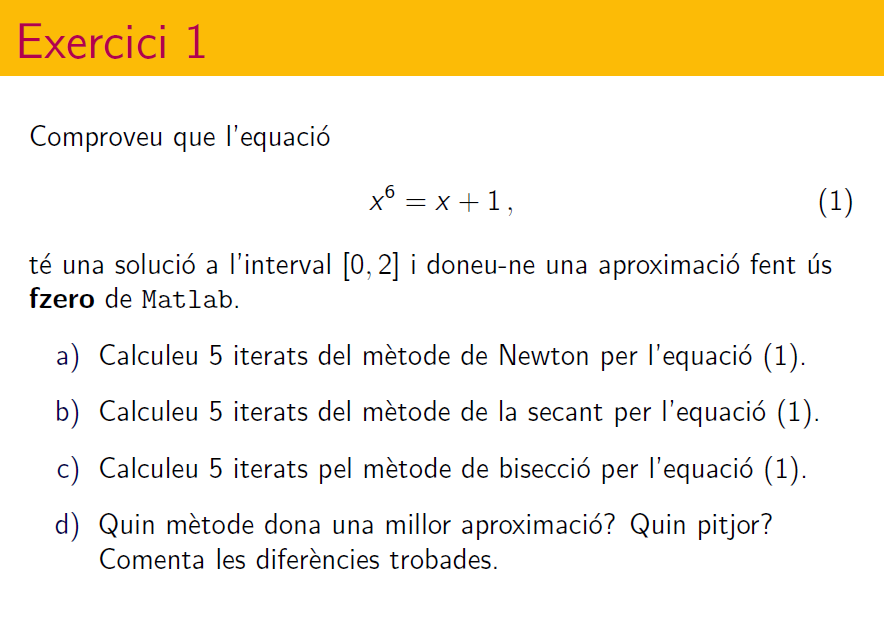

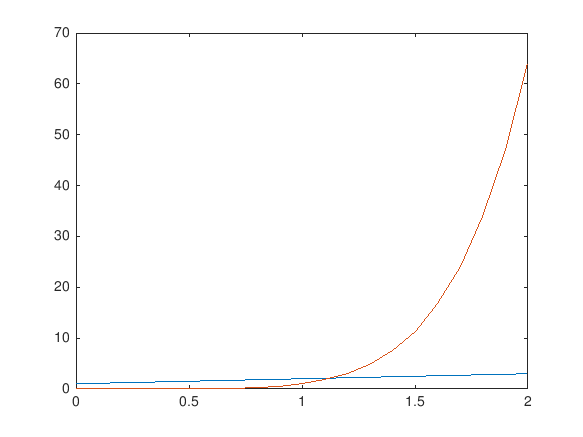

t = 0:0.1:2;
plot(t, t+1, t, t.^6)

## Verificació teorema de Bolzano

t = 1:0.05:1.3;
f=@(t)t.^6-t-1;
[t', f(t)']

ans =     1.0000   -1.0000
    1.0500   -0.7099
    1.1000   -0.3284
    1.1500    0.1631
    1.2000    0.7860
    1.2500    1.5647
    1.3000    2.5268


## Método de la Bisección

a=1.1; 
b=1.15; 
tol = eps;
nmax= 5;
[zero_b, res_b, niter_b] = bisection(f, a, b, tol, nmax)

zero_b = 1.1352

res_b = 0.0045

niter_b = 5

## Método de Newton

f=@(t)t.^6-t-1;
df=@(t)6*t.^5-1;
x0=1.1;
tol=eps;
nmax=5;
[zero_n, tolf_n, niter_n] = newton(f ,df ,x0 ,tol, nmax)

 No converge en el numero maximo  El iterante devuelto tiene un residuo 

zero_n = 1.1347

tolf_n = 8.8818e-16

niter_n = 5

## Método de la secante

a=1.1; 
b=1.15; 
tol = eps;
nmax= 5;
[zero_s, res_s, niter_s] = secante(f, a, b, tol, nmax)

zero_s = 1.1347

res_s = -8.8818e-16

niter_s = 5

## Método del punto fijo

a = 1.1; b = 1.2; tol = 0.00005; nmax =5 ;
%g = @(x) x.^6-1;
g = @(x)nthroot(x+1, 6);
x = a+0.5*(b-a);
k = 0;
tolx = 1; tolf = 1;
R = [k, x, tolf, tolx];
while (tolx > tol) && (tolf > tol) && (k < nmax)
    y = g(x);
    tolx = abs(y-x);
    tolf = abs(f(y));
    x = y;
    k = k+1;
    R = [R; k, x, tolf, tolx];
end
format short g
R

R =             0         1.15            1            1
            1       1.1361     0.013927     0.013927
            2       1.1348    0.0012298    0.0012298
            3       1.1347   0.00010892   0.00010892
            4       1.1347   9.6493e-06   9.6493e-06


## Teorema de Convergéncia

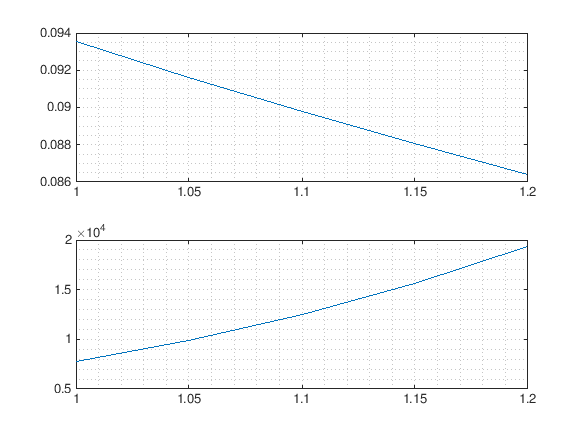

g1 = @(x)nthroot((x+1), 6);
dg1 = @(x)1./(nthroot((x+1).^5, 6)*6);
g2 = @(x)x.^6-1;
dg2 = @(x)(6*x).^5;
x=1:0.05:1.2;
subplot(211),plot(x, dg1(x)),grid minor
subplot(212),plot(x, dg2(x)),grid minor

## Tabla con resultados

x0 = [0 2];
options = optimset('Display', 'iter'); 
[x fval exitflag output] = fzero(f, x0, options);

 
 Func-count    x          f(x)             Procedure
    2               0            -1        initial
    3       0.0322581      -1.03226        interpolation
    4         1.01613     -0.915368        bisection
    5         1.01613     -0.915368        bisection
    6         1.06041     -0.638631        interpolation
    7         1.15599      0.230262        interpolation
    8         1.13066    -0.0414369        interpolation
    9         1.13452   -0.00210403        interpolation
   10         1.13472   1.55966e-06        interpolation
   11         1.13472  -7.71665e-10        interpolation
   12         1.13472  -8.88178e-16        interpolation
   13         1.13472  -8.88178e-16        interpolation
 
Zero found in the interval [0, 2]


A = [zero_b, f(zero_b), niter_b, ;
     zero_n, f(zero_n), niter_n;
     zero_s, f(zero_s), niter_s];
T = array2table(A,'VariableNames',{'x','f_x','iters'})

T = 3×3 table
      x           f_x        iters
    ______    ___________    _____

    1.1352        0.00445      5  
    1.1347    -8.8818e-16      5  
    1.1347    -8.8818e-16      5  
